clear;clc;close all
layerfolder='../data/layers/';%Route to folder with ambiental data
Dimensions = ReadLayers(layerfolder); %The 19 environmental variables for all the map

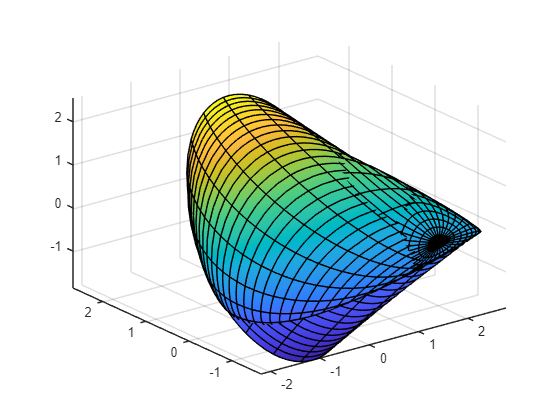

Elapsed time is 17.706521 seconds.


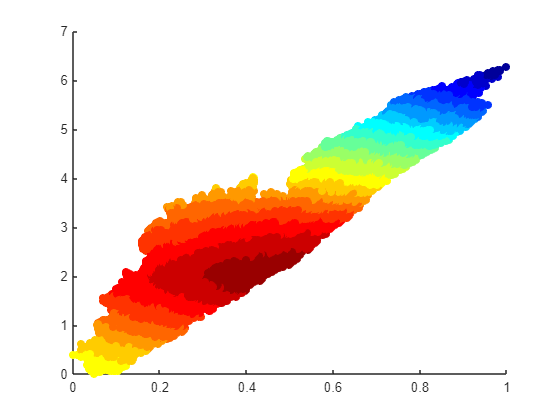

Elapsed time is 18.046564 seconds.


InfoInitialPoint = InitialPoint(Dimensions, 'harmonic'); %Generate a initial point to generate a niche

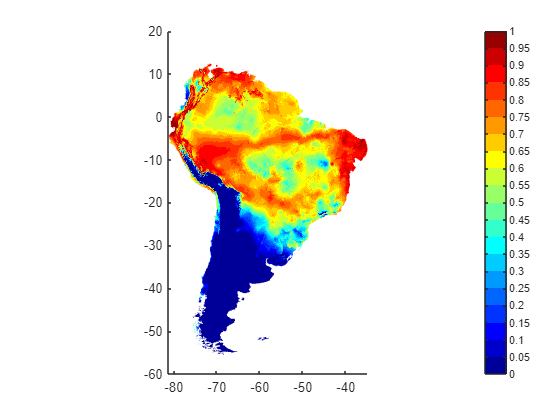

MapInfo = NicheGeneration(Dimensions, InfoInitialPoint, 0.8, true); %Generate the niche based on the initial point

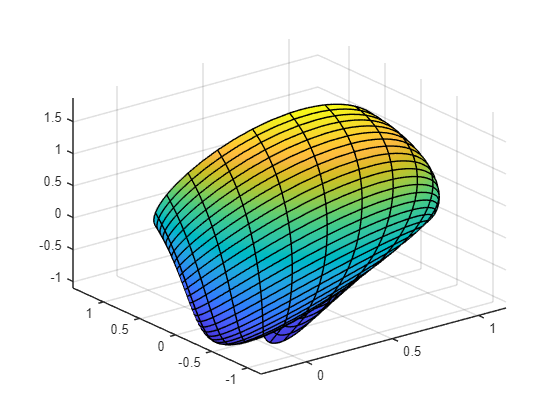

Elapsed time is 25.344943 seconds.


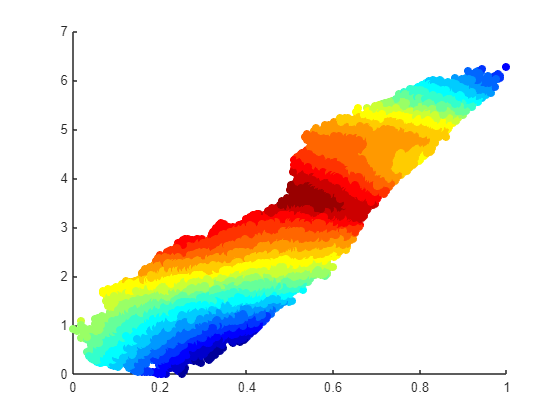

Elapsed time is 25.690237 seconds.


InfoInitialPointContaminated = InitialPoint(Dimensions, 'harmonic'); %Generate a initial point to generate a niche

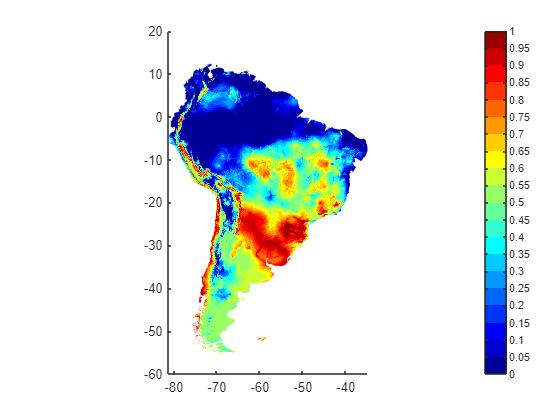

MapInfoContaminated = NicheGeneration(Dimensions, InfoInitialPointContaminated, 0.8, true); %Generate the niche based on the initial point

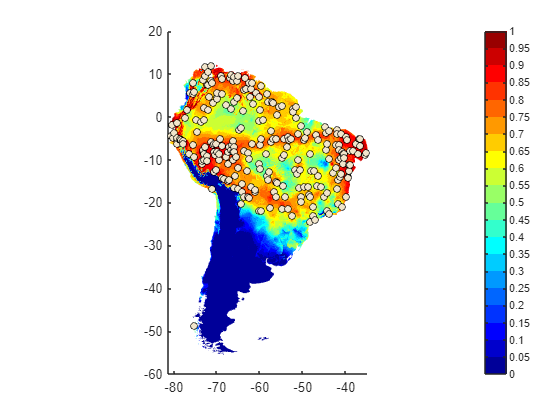

T = samplingVS(Dimensions, InfoInitialPoint, MapInfo, 250, -3, true, 'GenSP', true, true); %Generate samples based on the generated niche

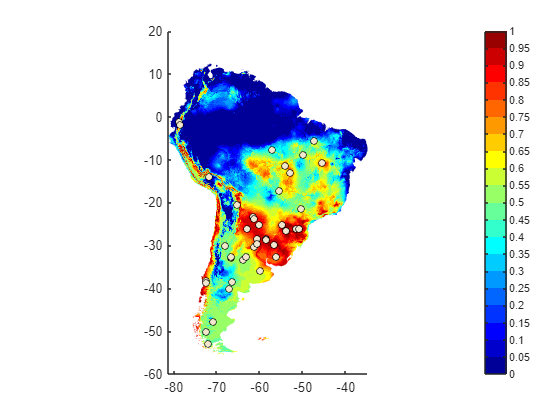

N = 40;
newT = samplingVS(Dimensions, InfoInitialPointContaminated, MapInfoContaminated, N, -3, true, 'GenSP', true, true);

contaminatedT = T;
size = height(T);
contaminatedT(size+1:size+N,:) = newT(1:end,:);

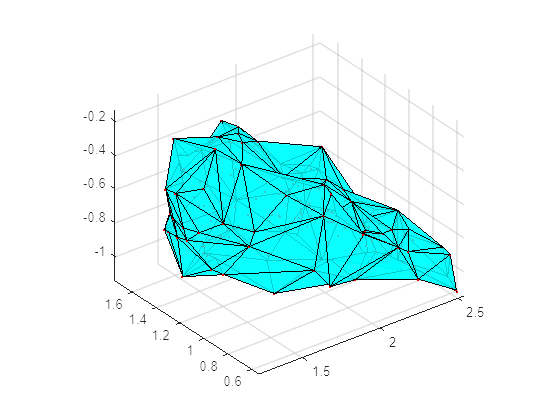

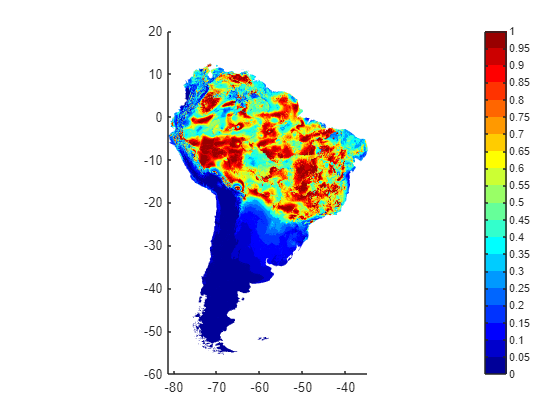

%ColoringBorder generates classifier object with atributes nodes = environmental variables
%for each frontier point, 
%T = table with samples and information
%readInfo = dimensions of the map
%alpha = shrinking factor

classA1 = ColoringBorder(contaminatedT,Dimensions,1,true,false,true); 

MapMetric(MapInfo.Map,classA1.map,false)

ans =     0.9030    0.8071


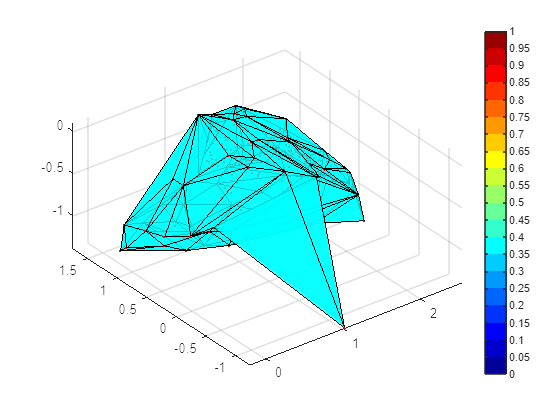

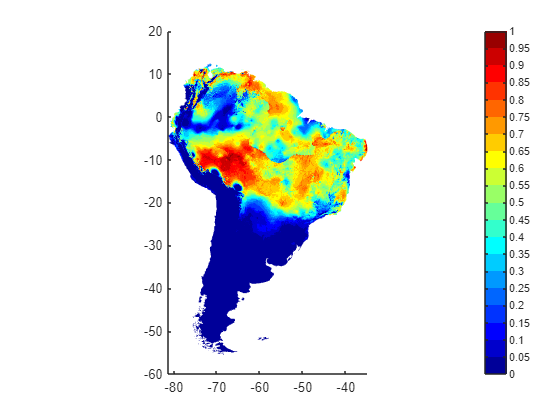

%T = table with samples and information
%readInfo = dimensions of the map
%percentile = percentile with which the radius will be taken
%alpha = shrinking factor

classB1 = ColoringRadius(contaminatedT,Dimensions,1,15,true,false,false); 

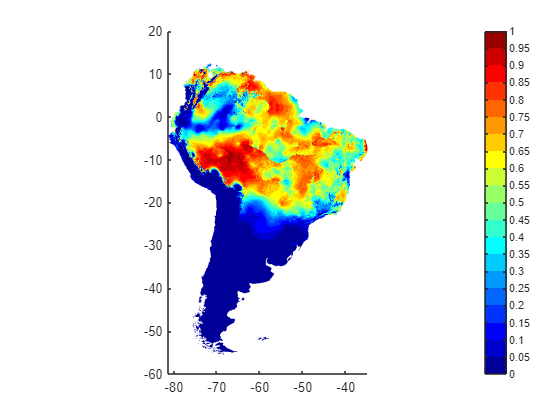

classB2 = ColoringRadiusPercentile(contaminatedT,Dimensions,1,25,true,false,false); 

MapMetric(MapInfo.Map,classA1.map,false) %accuracy of the generated colored map compared to the the original niche

ans =     0.9030    0.8071


MapMetric(MapInfo.Map,classB1.map,false) 

ans =     0.9700    0.8108


MapMetric(MapInfo.Map,classB2.map,false) 

ans =     0.9551    0.7855
